# Skin Lesion Classification via CNN Transfer Learning

Last updated: October 2, 2021

#### Load dataset

dataLocation = "Dataset/ISIC_2019_Training_Input"

dataLocation = "Dataset/ISIC_2019_Training_Input"

labelsLocation = "Dataset/groundtruth_categorical.csv"

labelsLocation = "Dataset/groundtruth_categorical.csv"

Create a datastore for the raw images

image_datastore = imageDatastore(dataLocation);
num_images = length(image_datastore.Files);

Import ground truth labels

groundtruth = readtable(labelsLocation);
image_datastore.Labels = categorical(groundtruth.category(1:num_images));
labelCounts = countEachLabel(image_datastore)

labelCounts = 8×2 table
             Label             Count
    _______________________    _____

    Actinic keratosis            867
    Basal cell carcinoma        3323
    Benign keratosis            2624
    Dermatofibroma               239
    Melanocytic nevus          12875
    Melanoma                    4522
    Squamous cell carcinoma      628
    Vascular lesion              253


minCategoryImageCount = min(labelCounts.Count);

Display some images with their labels

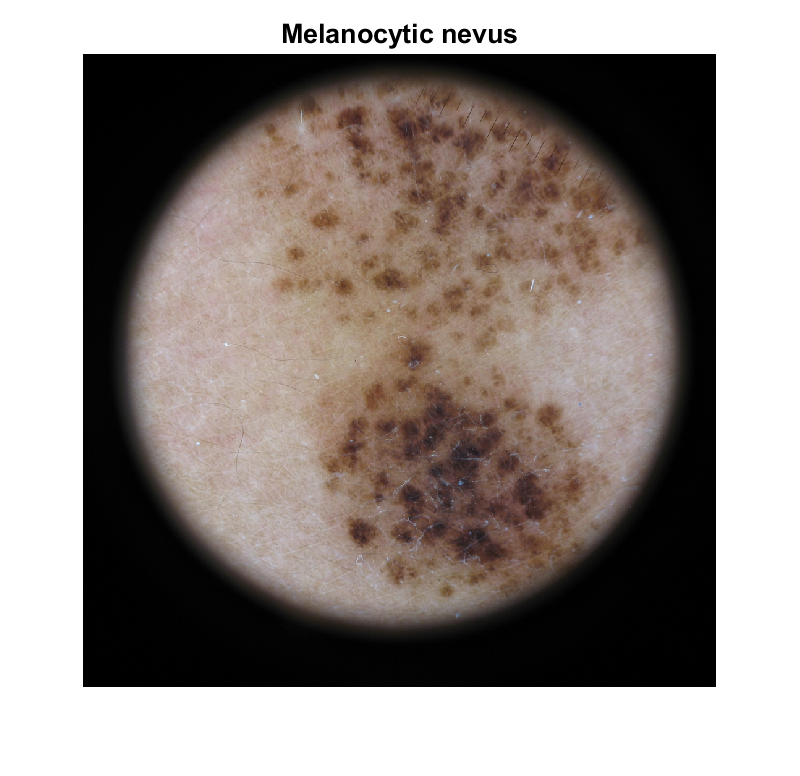

sample_idx = 18371;
imshow(readimage(image_datastore, sample_idx));
title(image_datastore.Labels(sample_idx), 'FontSize', 20);

#### Split dataset into training set, validation set, and test set.

[trainImds, valImds, testImds] = splitEachLabel(image_datastore, 0.8,0.1, 'randomized');

#### Image augmentation and regularization

trainds = augmentedImageDatastore([224,224], trainImds);
valds = augmentedImageDatastore([224,224], valImds);
testds = augmentedImageDatastore([224,224], testImds);



### Import and modify pretrained Neural Network

net = googlenet;
lgraph = layerGraph(net);

newFc = fullyConnectedLayer(numel(labelCounts.Label),"Name","new_fc");
lgraph = replaceLayer(lgraph,"loss3-classifier",newFc);
newOut = classificationLayer("Name","new_out");
lgraph = replaceLayer(lgraph,"output",newOut);

### Set training options

Stochastic Gradient Descent with Momentum

Learning rate = 0.001

options = trainingOptions("sgdm","InitialLearnRate", 0.001,'MiniBatchSize',128/2, 'MaxEpochs', 400,'Plots','training-progress')

options =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9000
                InitialLearnRate: 1.0000e-03
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 400
                   MiniBatchSize: 64
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: []
             ValidationFrequency: 50
              ValidationPatience: Inf
                         Shuffle: 'once'
                  CheckpointPath: ''
            ExecutionEnvironment: 'auto'
                      WorkerLoad: []
                       OutputFcn: []
                           Plots: 'training-progress'
                  SequenceL

### Train the neural network

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:04 |        6.25% |       3.9564 |          0.0010 |
|       1 |          50 |       00:01:15 |       45.31% |       1.2800 |          0.0010 |
|       1 |         100 |       00:02:27 |       62.50% |       0.9133 |          0.0010 |
|       1 |         150 |       00:03:41 |       64.06% |       1.0171 |          0.0010 |
|       1 |         200 |       00:04:53 |       73.44% |       0.8896 |          0.0010 |
|       1 |         250 |       00:06:04 |       67.19% |       0.8708 |          0.0010 |
|       1 |         300 |  

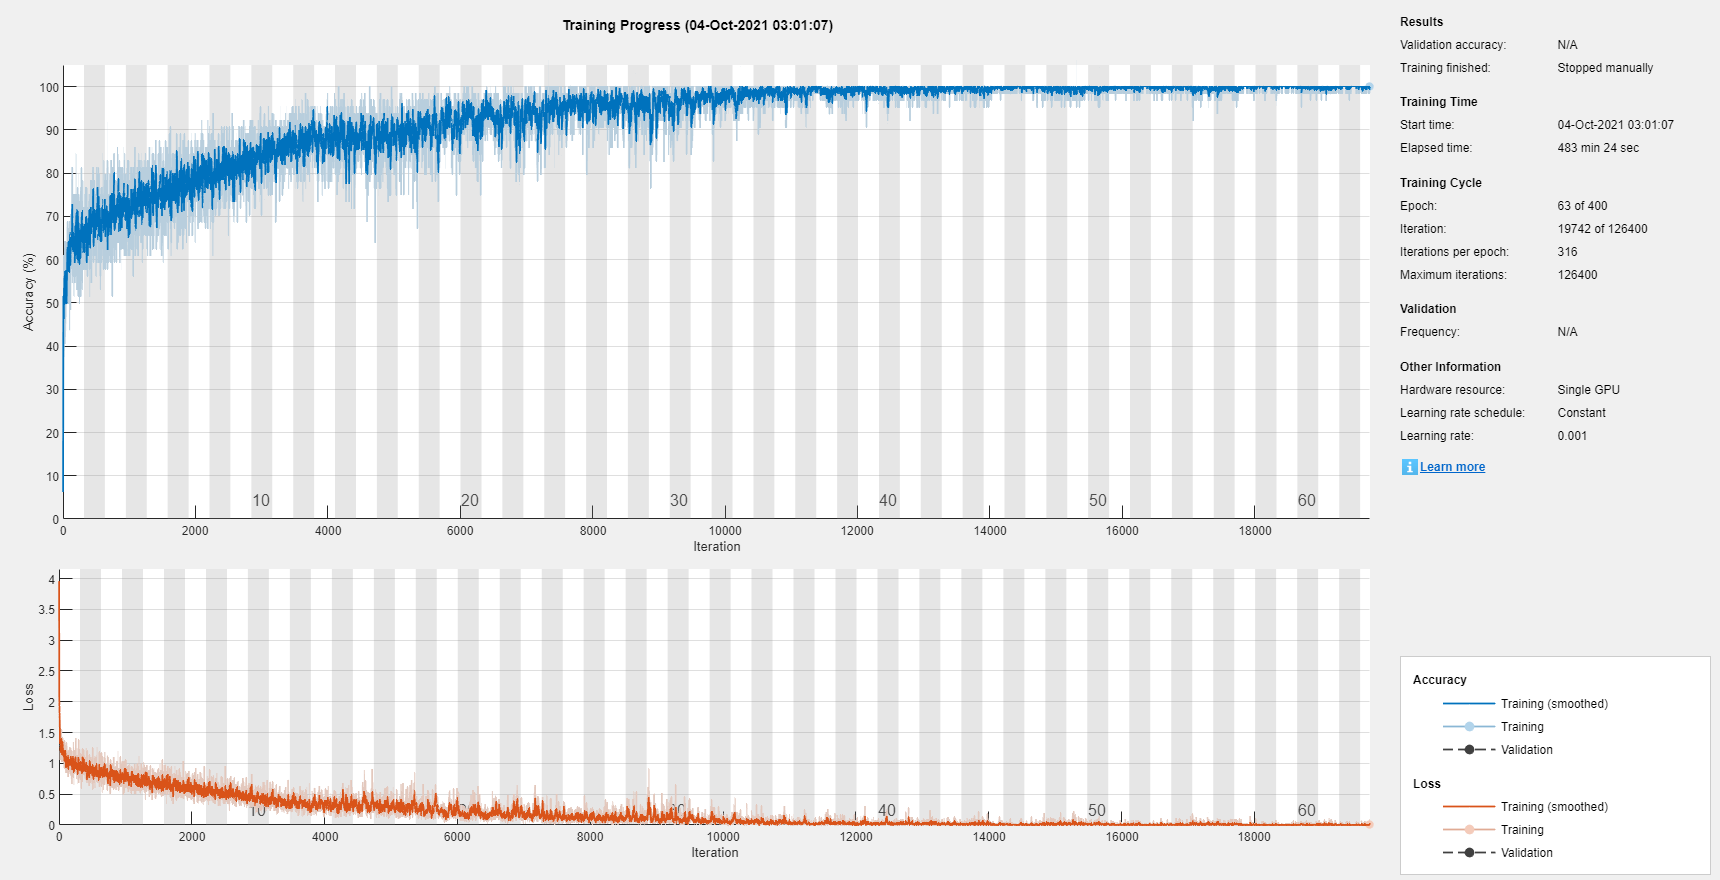

lesionNet = trainNetwork(trainds, lgraph, options);

Save trained model to device

save lesionNet_prev.mat lesionNet;

#### Evaluate network on Validation set

preds = classify(lesionNet, valds);
valTrue = valImds.Labels;

accuracy = 0.7748

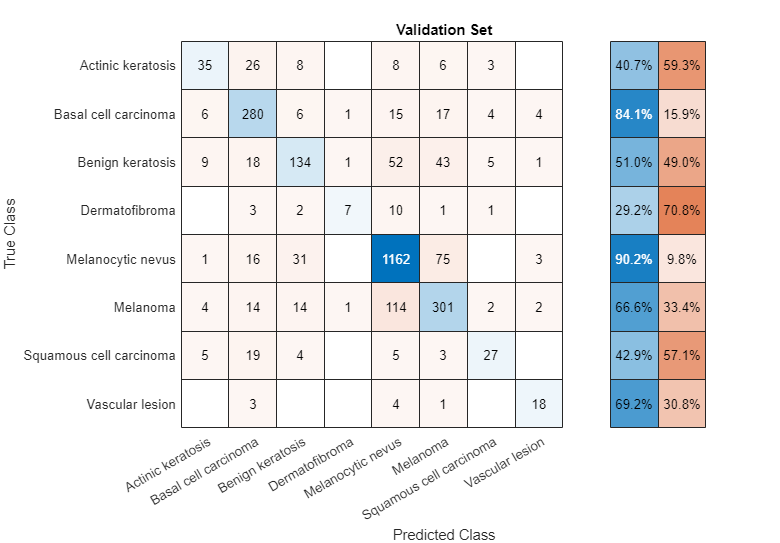

accuracy = nnz(preds == valTrue)/numel(preds)

confusionchart(valTrue, preds, 'RowSummary','row-normalized', 'Title',"Validation Set");

### Visualize failed predictions

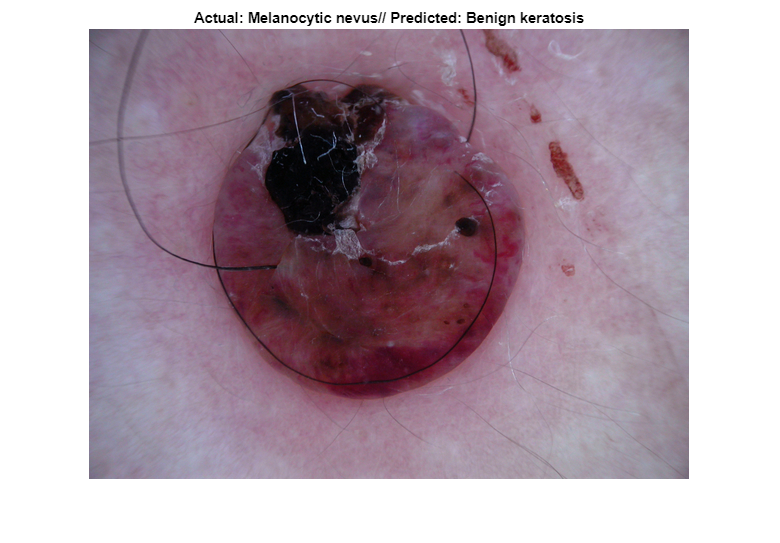

failedPredictions = find(preds~=valTrue);
num_fail = numel(failedPredictions);
failedSample = 235;
if ~isempty(failedPredictions)
    imshow(readimage(valImds,failedPredictions(failedSample)), 'InitialMagnification', 100);
    title("Actual: " + string(valTrue(failedPredictions(failedSample))) + "// Predicted: " + string(preds(failedPredictions(failedSample))))
end

### Visualize correct predictions

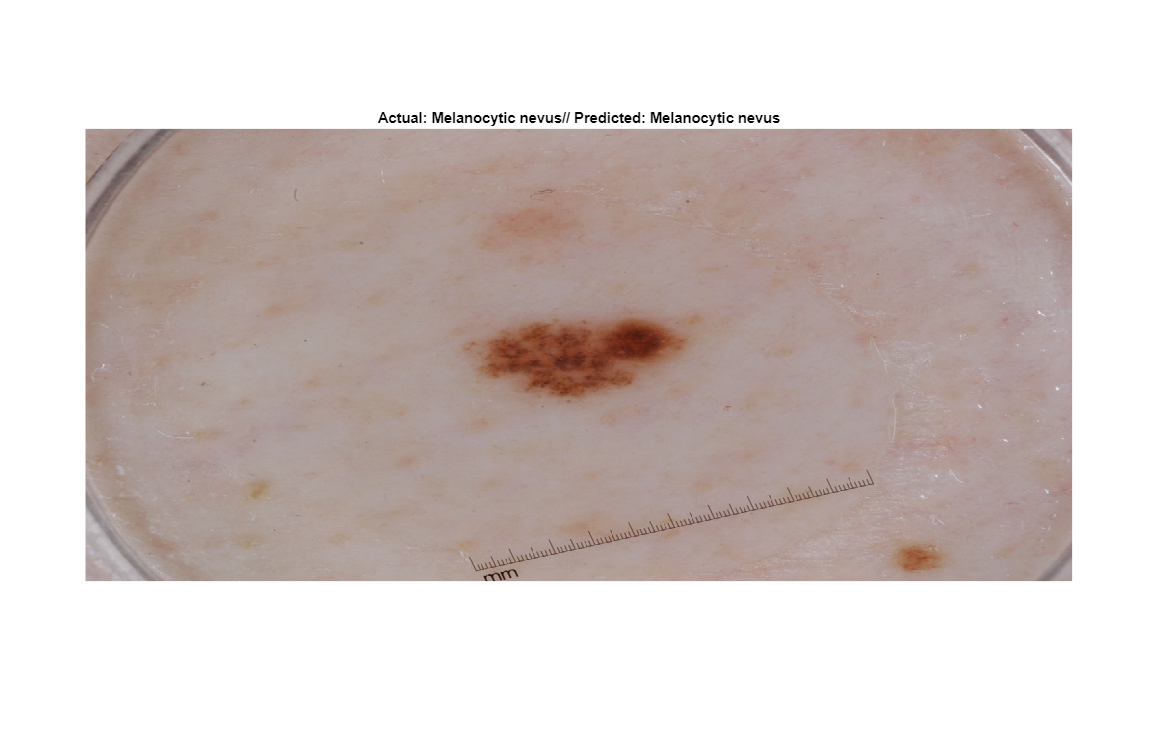

correctPredictions = find(preds==valTrue);
num_correct = numel(correctPredictions);
correctSample = 213;
if ~isempty(correctPredictions)
    imshow(readimage(valImds,correctPredictions(correctSample)), 'InitialMagnification', 100);
    title("Actual: " + string(valTrue(correctPredictions(correctSample))) + "// Predicted: " + string(preds(correctPredictions(correctSample))))
end

### Evaluate network on test set

preds = classify(lesionNet, testds);
testTrue = testImds.Labels;
accuracy = nnz(preds == testTrue)/numel(preds)
confusionchart(testTrue, preds, 'RowSummary','row-normalized', 'Title',"Test Set");